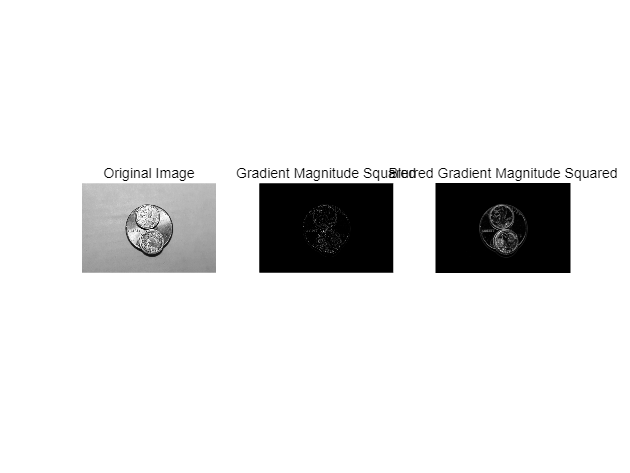


% Load the image
image = imread('coin_2.jpg');
grayImage = rgb2gray(image);

% gradient magnitude squared
[gradientX, gradientY] = gradient(double(grayImage));
gradientMagnitudeSquared = gradientX.^2 + gradientY.^2;

% Blur the gradient magnitude squared with Gaussian filter
sigma = 2; % STD for gaussian
blurredGradient = imgaussfilt(gradientMagnitudeSquared, sigma);

figure;
subplot(1, 3, 1); imshow(grayImage, []); title('Original Image');
subplot(1, 3, 2); imshow(gradientMagnitudeSquared, []); title('Gradient Magnitude Squared');
subplot(1, 3, 3); imshow(blurredGradient, []); title('Blurred Gradient Magnitude Squared');

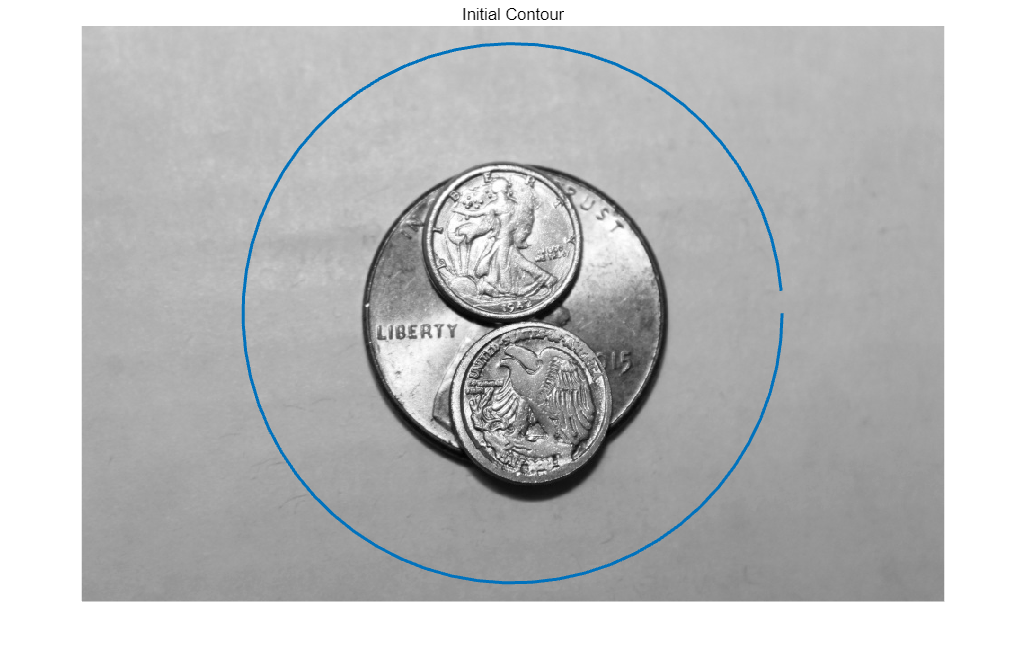


% Init contour circle
[x, y] = meshgrid(1:size(grayImage, 2), 1:size(grayImage, 1));
initialContourX = size(grayImage, 2) / 2 + 300 * cos(0:0.1:2*pi);
initialContourY = size(grayImage, 1) / 2 + 300 * sin(0:0.1:2*pi);
contour = [initialContourX(:), initialContourY(:)];
% number of contour point
N = size(contour, 1);

figure; imshow(grayImage, []); hold on;
plot(initialContourX, initialContourY, 'LineWidth', 2);
title('Initial Contour');

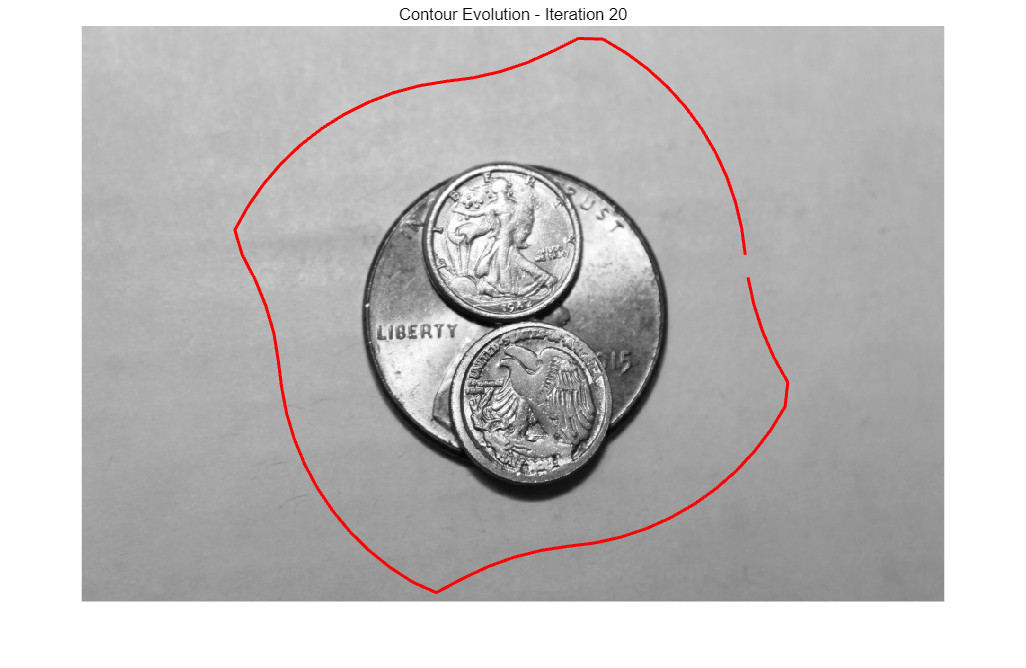

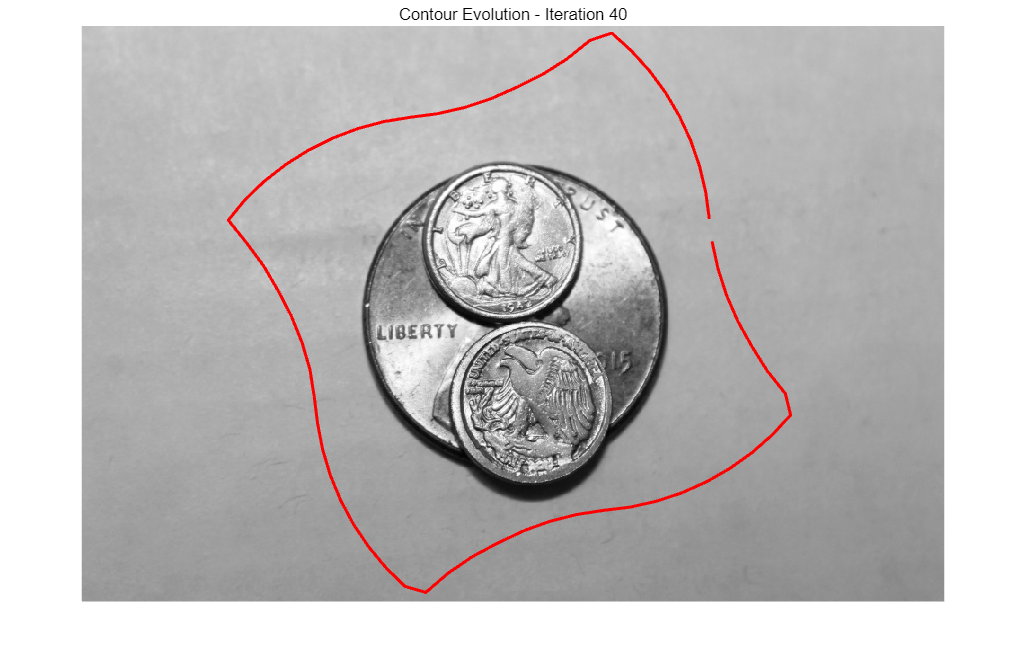

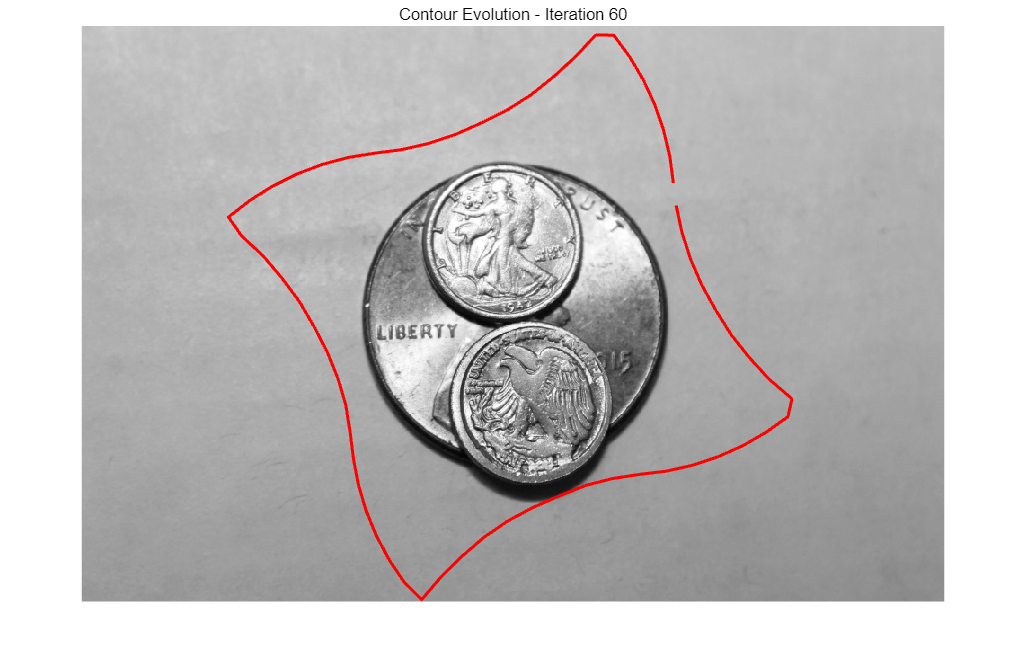

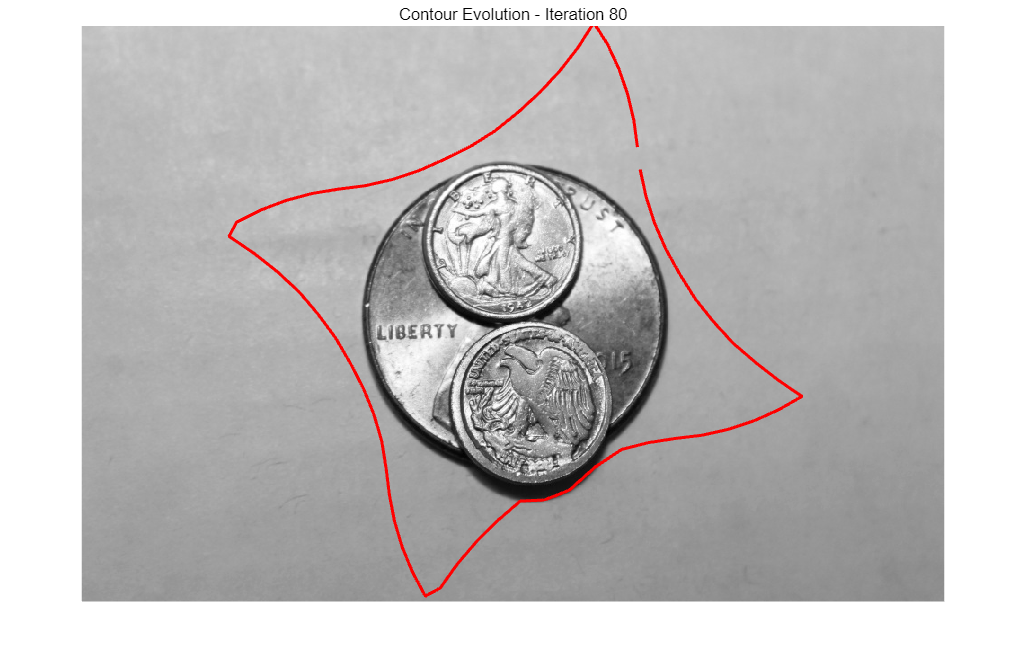

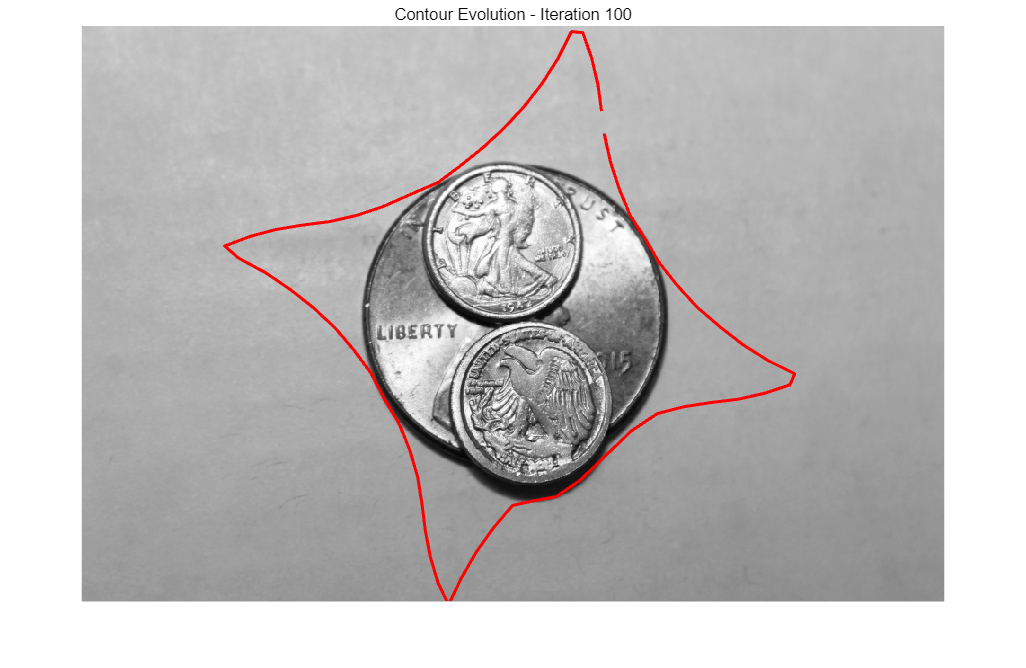


% Parameters
windowSize = 2; % Size of the local window for the greedy search
alpha = 0.95;    % Weight for elasticity
beta = 0.05 ;     % Weight for smoothness
threshold = 1e-3; % Convergence threshold
maxIterations = 100; % Maximum number of iterations

% Greedy Algorithm for Contour Evolution
for iter = 1:maxIterations
    contourUpdated = contour; % Copy the current contour
    totalMotion = 0; % Track total motion of all points
    
    for i = 1:N
        % windown def
        xi = contour(i, 1);
        yi = contour(i, 2);
        [xWindow, yWindow] = meshgrid(xi-windowSize:xi+windowSize, yi-windowSize:yi+windowSize);
        
        % Eimage in the window
        Eimage = interp2(x, y, -blurredGradient, xWindow, yWindow, 'linear', 0);
        
        % Elasticity
        prevPoint = contour(mod(i-2, size(contour, 1)) + 1, :);
        nextPoint = contour(mod(i, size(contour, 1)) + 1, :);
        Eelastic = alpha * ((xWindow - prevPoint(1)).^2 + (yWindow - prevPoint(2)).^2);

        % Smoothness
        Esmooth = beta * ((xWindow - 2*xi + nextPoint(1)).^2 + (yWindow - 2*yi + nextPoint(2)).^2);
        
        % Total energy
        Etotal = Eimage + Eelastic + Esmooth;

        % Find minimum energy, shift the window
        [~, minIndex] = min(Etotal(:));
        [row, col] = ind2sub(size(Etotal), minIndex);
        newXi = xWindow(row, col);
        newYi = yWindow(row, col);

        % Update contour points
        contourUpdated(i, :) = [newXi, newYi];
        
        % Calculate motion
        totalMotion = totalMotion + sqrt((newXi - xi)^2 + (newYi - yi)^2);
    end
    
    contour = contourUpdated;
    
    % Check for convergence
    if totalMotion < threshold
        disp(['Converged at iteration ', num2str(iter)]);
        break;
    end
    
    % show every 10 iterations
    if mod(iter, 20) == 0
        figure; imshow(grayImage, []); hold on;
        plot(contour(:, 1), contour(:, 2), 'r-', 'LineWidth', 2);
        title(['Contour Evolution - Iteration ', num2str(iter)]);
        pause(0.1);
    end
end

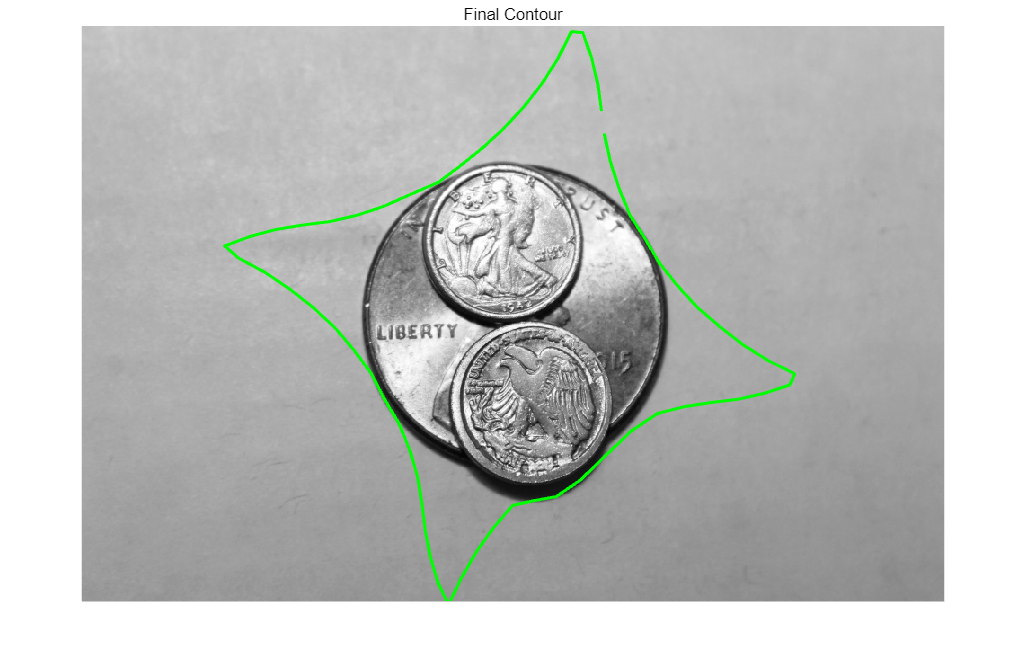


% final contour
figure; imshow(grayImage, []); hold on;
plot(contour(:, 1), contour(:, 2), 'g-', 'LineWidth', 2);
title('Final Contour');

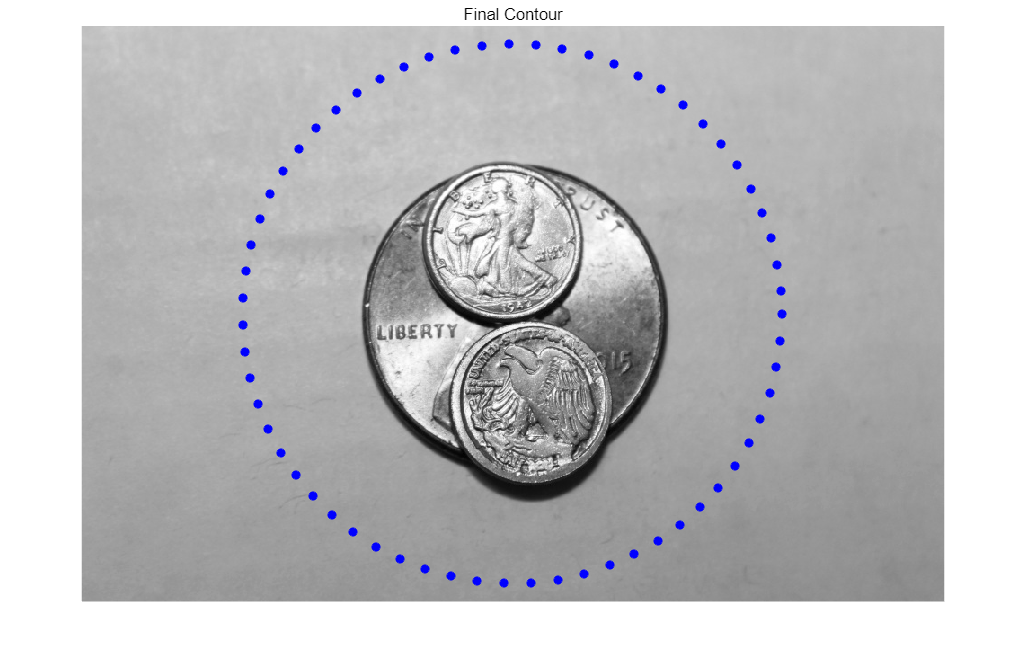

[x, y] = meshgrid(1:size(grayImage, 2), 1:size(grayImage, 1));
initialContourX = size(grayImage, 2) / 2 + 300 * cos(0:0.1:2*pi);
initialContourY = size(grayImage, 1) / 2 + 300 * sin(0:0.1:2*pi);
contour = [initialContourX(:), initialContourY(:)];
figure; imshow(grayImage, []); hold on;
plot(contour(:, 1), contour(:, 2), 'b*', 'LineWidth', 2);
title('Final Contour');